# Task 5: Incremental Fault Diagnosis Using Deep Learning Models

## **1. Develop Deep Learning Model for Fault Diagnosis **

In this exercise, we will train a convolutional neural network (CNN), a widely used deep learning model for fault diagnosis. Instead of using extracted features, we will use the raw data directly for model training, validation, and testing.

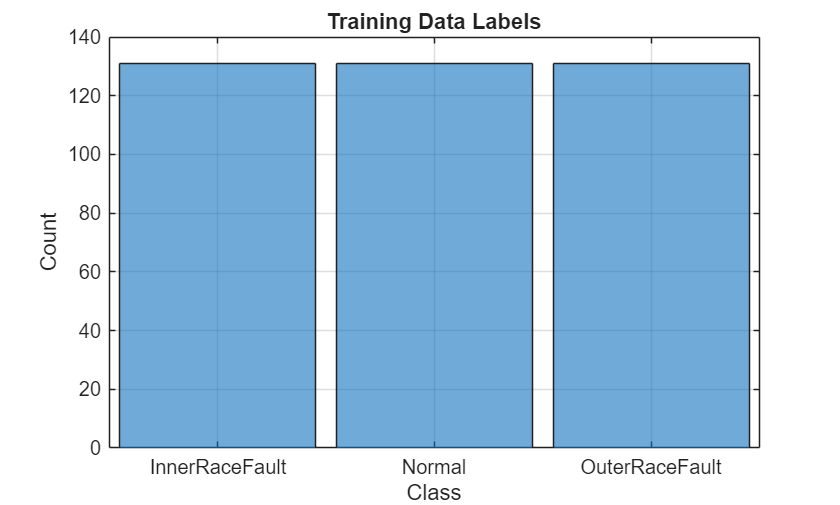

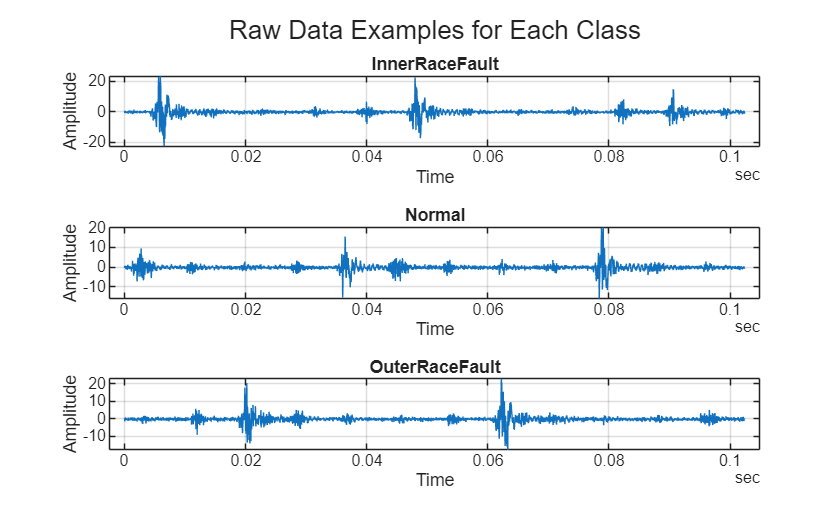

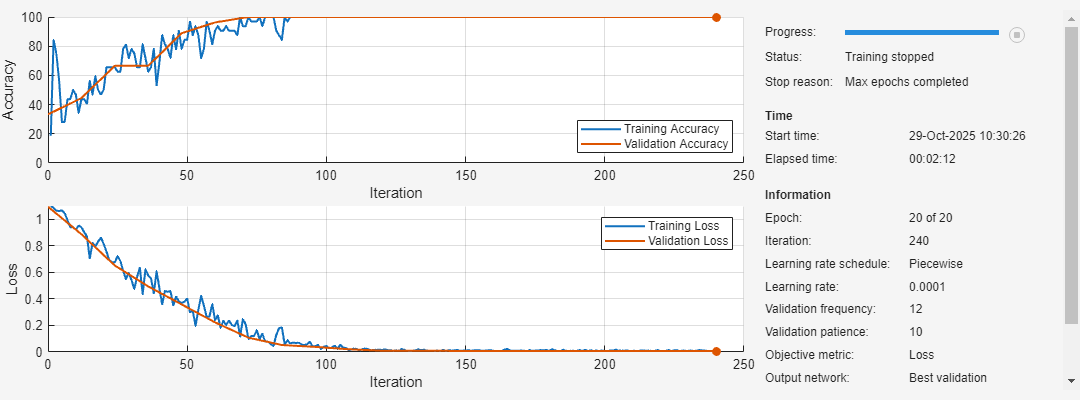

accuracy = 1

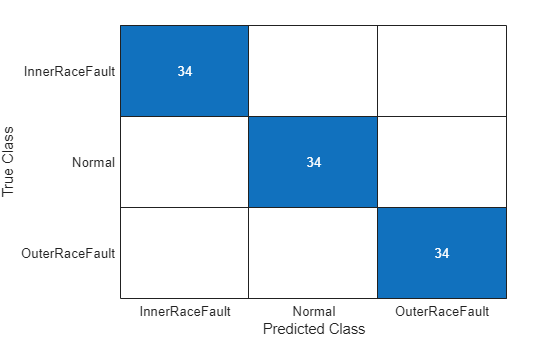

load("valTable.mat")

load("trainTable.mat")
load("testTable.mat")
plotRawData(trainTable)

Prepare data from original dataset for training, validation and testing

% Prepare Data
allTrainData = cell2mat(trainTable{:,4});
muTrain = table2array(mean(allTrainData));
sigmaTrain = table2array(std(allTrainData));
% Get Training Data and Normalize
XTrain = cellfun(@(tt) (tt.gs - muTrain) ./ sigmaTrain,table2cell(trainTable(:,4)),'UniformOutput',false);
XTest = cellfun(@(tt) (tt.gs - muTrain) ./ sigmaTrain,table2cell(testTable(:,4)),'UniformOutput',false);
XVal = cellfun(@(tt) (tt.gs - muTrain) ./ sigmaTrain,table2cell(valTable(:,4)),'UniformOutput',false);
YTrain = categorical(string(trainTable.label));
YTest = categorical(string(testTable.label));
YVal = categorical(string(valTable.label));
% Shuffle Training Data
mask = randperm(size(XTrain,1));
XTrain = XTrain(mask,:);
YTrain = YTrain(mask,:);

## **2. Define and Train the Network **

You can use Deep Network Designer App to develop the structure of a neural network. In this exercise we will use the command line interface:

numClasses = numel(categories(YTrain));
minLength=256;
net = [
    sequenceInputLayer(1,MinLength=minLength,Normalization="zerocenter")
    convolution1dLayer(256, 32, 'Padding','same','Name','conv1')
    reluLayer('Name','relu1')
    convolution1dLayer(16, 8, 'Padding','same','Name','conv2')
    reluLayer('Name','relu2')
    dropoutLayer(0.1)
    globalAveragePooling1dLayer
    fullyConnectedLayer(128,'Name','fc1')
    fullyConnectedLayer(numClasses,'Name','fc2')
    softmaxLayer('Name','softmax')
];

Next we can set training options and train the CNN network with training data. The training process is validated with the validation data.

miniBatchSize=32;
validationFrequency = floor(size(XTrain,1)/miniBatchSize);
if canUseGPU
    trainOn = "gpu";
else
    trainOn = "cpu";
end
options = trainingOptions("adam", ...
    Metric="accuracy", ...
    MiniBatchSize=miniBatchSize, ...
    MaxEpochs=20, ...
    Plots="training-progress", ...
    Verbose=false, ...
    Shuffle="every-epoch", ...
    LearnRateSchedule="piecewise", ...
    ValidationData={XVal,YVal}, ...
    ValidationFrequency=validationFrequency, ...
    ValidationPatience=10, ...
    OutputNetwork="best-validation-loss", ...
    ExecutionEnvironment=trainOn);

Once the network structure is defined and training options are set, you can execute the code below to train the model. Note if GPU is availabe on the host machine, the training will be performed in GPU.

net = trainnet(XTrain,YTrain,net,"crossentropy",options);
% save('original_net.mat','net');

## **3. Evaluate Model with Testing Data**

Once the model has been trained and validated, you can evaluate its performance on the testing dataset. 

YPredOriginal = scores2label(minibatchpredict(net, XTest),unique(YTrain));
accuracy = sum(YPredOriginal == YTest)/numel(YTest)
figure
confusionchart(YTest,YPredOriginal)

**Helper Function**

function plotRawData(originalData)
labels = string(originalData.label); % Directly access the Label column
unqiqueLabels = unique(labels);
figure;
histogram(categorical(labels, unique(labels)), 'DisplayOrder', 'ascend');
xlabel('Class',Interpreter='none');
ylabel('Count',Interpreter='none');
title('Training Data Labels',Interpreter='none');
grid on;

figure('Name','Raw Data ');tiledlayout(3,1)
numClasses = numel(unqiqueLabels);
for c = 1:numClasses
    nexttile
    TT = originalData.data{c};
    plot(TT.Time,TT.gs);
    xlabel('Time');
    ylabel('Amplitude');
    title(unqiqueLabels(c), 'Interpreter','none');
    grid on;
end
sgtitle('Raw Data Examples for Each Class');
end


